% segment leaves
function result = segment_leaf_watershed(I, info)
    I_rgb = im2double(I);

    %convert image to Lab color space
    I_lab = rgb2lab(I_rgb);
    I_a = I_lab(:,:,2);

    % SLIC
    [L,N] = superpixels(I_lab,10000, Compactness=1, NumIterations=100, IsInputLab=true);
    % get mean intensity a* channel of superpixels L 
    meanColors = regionprops(L, I_a, 'MeanIntensity');
    meanColors = [meanColors.MeanIntensity];
    
    % get foreground by thresholding the mean intensity from the last step 
    threshold = -15;
    plantSuperpixels = find(meanColors < threshold);
    plantMask = ismember(L, plantSuperpixels);

    % smoothening the edges
    se_smooth = strel('square',3);
    plantMask = imopen(plantMask,se_smooth);

    distanceMap = bwdist(~plantMask);
    centroids = regionprops(plantMask, distanceMap, 'Centroid');
    centroids = cat(1, centroids.Centroid);
    [row,col]=size(plantMask);
    [X,Y] = meshgrid(1:col,1:row);
    coordinates=centroids;

    numel_row = numel(coordinates(:,1));
    markers = zeros(numel_row, 1);
    for i = 1:numel_row
        x = coordinates(i, 1);
        y = coordinates(i, 2);
        x = uint8(x);
        y = uint8(y);
        markers(i) = L(y, x);
    end
    maskMarker = ismember(L, markers);
    
    %make the marker/seed bigger
    se_marker = strel('square',10); 
    maskMarker = imdilate(maskMarker, se_marker);

    DL = watershed(~maskMarker);
    bgm = DL == 0;

    I_gmag = imgradient(rgb2gray(I_rgb)); 
    I_gmag2 = imimposemin(I_gmag, bgm | maskMarker);
    L = watershed(I_gmag2);
    L = L-1;
    Lrgb = label2rgb(L,"jet","k","shuffle");
    %imwrite(L, info);
    result = L;
end

%directory = "G:\Documents\Github\LeafSAM\dataset\Komatsuna\rgbd_plant";
directory = "G:\Documents\Github\LeafSAM\dataset\CVPPP\train\images\A1\"

directory = "G:\Documents\Github\LeafSAM\dataset\CVPPP\train\images\A1\"

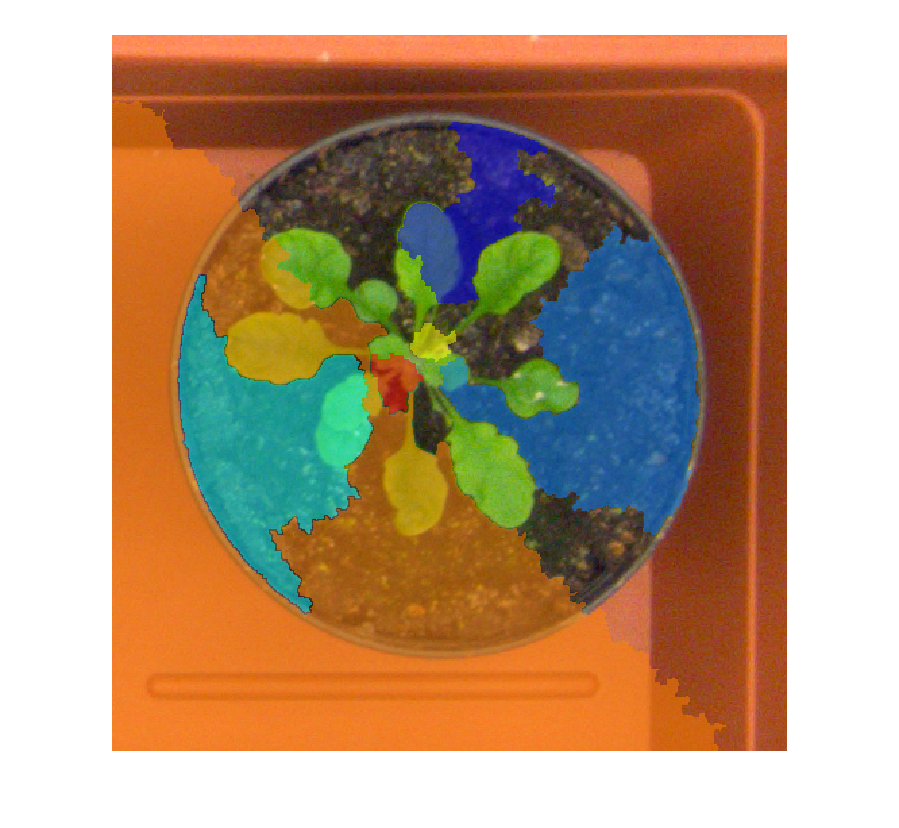

imds = imageDatastore(directory,"FileExtensions", [".jpg",".png"]);
while hasdata(imds)
    [I,info ]= read(imds);
    [folder, baseFile, ext] = fileparts(info.Filename);
    fln = strcat("G:\Documents\Github\Leaf_DIP", "\CVPPPA1\",baseFile, ext);
    i = segment_leaf_watershed(I, fln);
    leafOverlay = labeloverlay(I,i);
    imshow(leafOverlay)
end